# Problem 22.13

clear, constants

k =      8.99e+09

e0 =      8.85e-12

e =     1.602e-19

R = 2e-2

R =          0.02

Electric force on the proton, p, on the z-axis due to two electrons on the edge of the distk: $E_{s,z} = -2k\frac{ez}{(z^2+R^2)^{3/2}}$

Esz = @(z) -2*k*e*z./(z.^2+R^2).^(3/2)  % z-component of electric field due to two es

Esz = function_handle with value:
    @(z)-2*k*e*z./(z.^2+R^2).^(3/2)

(a) Electric field due to electron $e_c$

abs(-k*e/R^2)   % magnitude

ans =    3.6005e-06

(b) Net electric field due to electrons

abs(Esz(R))

ans =    2.5459e-06

(c) z = R/10

abs(-k*e/(R/10)^2)

ans =    0.00036005

(d) Net electric field due to electrons at z = R/10

abs(Esz(R/10))

ans =    7.0943e-07

$E_{s,net}$ plot

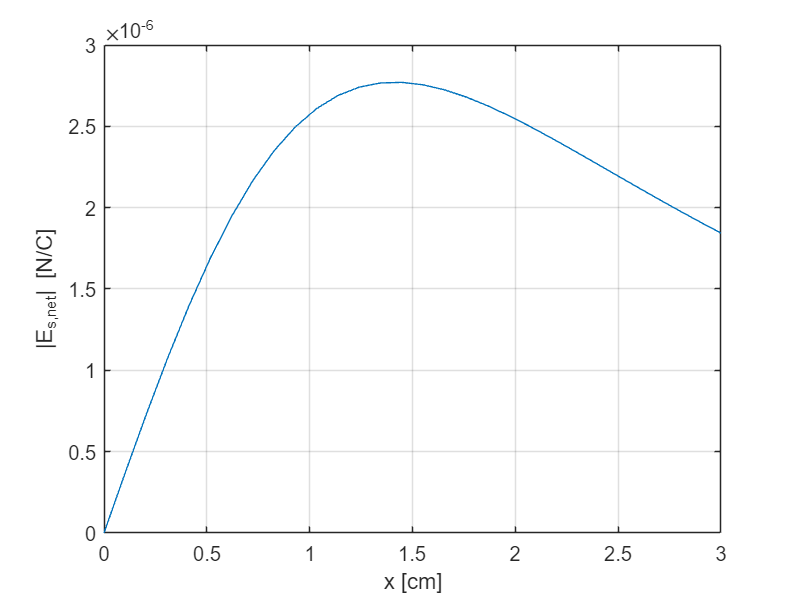

z = linspace(0,3e-2,30);
Enetz = Esz(z);
plot(z*100,abs(Enetz)), grid on, xlabel('x [cm]'), ylabel('|E_{s,net}| [N/C]')